%DSP lab 01
%activity 01 part a:
function X = fDFT(x)
    N = length(x);
    X = zeros(1,N);
    for k=0 : N-1
        for n=0 : N-1
            X(k+1) = X(k+1) + x(n+1) * exp(-1j*2*pi*k*n/N);
        end
    end
end

function x = iDFT(X)
    N = length(X);
    x = zeros(1,N);
    for n = 0:N-1
        for k = 0:N-1
            x(n+1) = x(n+1) + X(k+1) * exp(1j*2*pi*k*n/N);
        end
    end
    x = x/N;
end

% part b of activity 1.1:
clear;
clear all;
x = [1, 1, 1, 1, 1, 1, 1, 1, 1, 1];
X= fDFT(x)

X =   10.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i


x_inv = iDFT(X);
subplot(2,1,1);
stem(0:9, x, 'filled');
title('Original Signal x[n]');
xlabel('n');
ylabel('Amplitude');
grid on;

%now plotting the frdft graph:
subplot(2,1,2);
stem(0:9, X, 'filled');

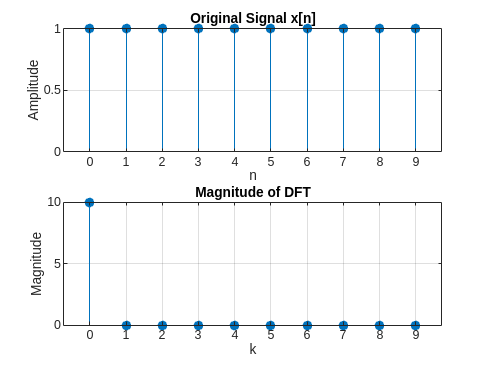

title('Magnitude of DFT');
xlabel('k');
ylabel('Magnitude');
grid on;


%now plotting the idft graph
subplot(3,1,3);
stem(0:9, x_inv, 'filled'); 

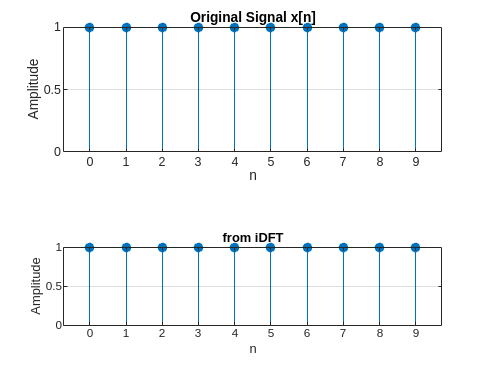

title('from iDFT');
xlabel('n');
ylabel('Amplitude');
grid on;

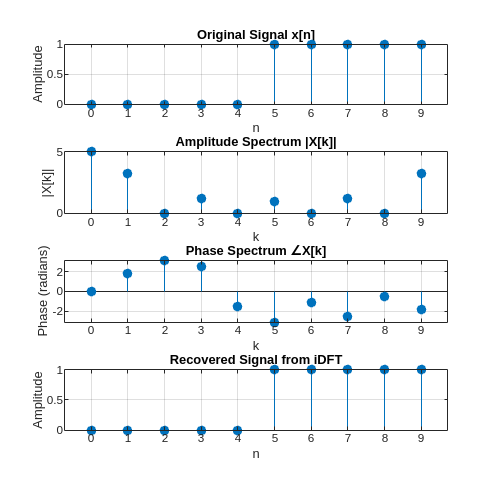

%activity 1.2:
close all;
clc;

%part a: Original signal
x = [0, 0, 0, 0, 0, 1, 1, 1, 1, 1]; %this is our input signal
X = fDFT(x);

%Create a new figure with 4 subplots
figure;

%Plot original signal
subplot(4,1,1);
stem(0:9, x, 'filled');
title('Original Signal x[n]');
xlabel('n');
ylabel('Amplitude');
grid on;

%part b: Amplitude spectrum
subplot(4,1,2);
stem(0:9, abs(X), 'filled');
title('Amplitude Spectrum |X[k]|');
xlabel('k');
ylabel('|X[k]|');
grid on;

%Phase spectrum
subplot(4,1,3);
stem(0:9, angle(X), 'filled');
title('Phase Spectrum ∠X[k]');
xlabel('k');
ylabel('Phase (radians)');
grid on;

%part c: Recovered signal
xinv = iDFT(X);
subplot(4,1,4);
stem(0:9, real(xinv), 'filled');
title('Recovered Signal from iDFT');
xlabel('n');
ylabel('Amplitude');
grid on;

% Adjust figure to prevent overlap
set(gcf, 'Position', [100, 100, 800, 800]);

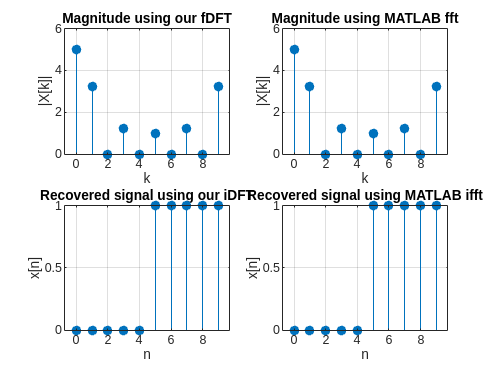

%activity 1.3:
x = [0, 0, 0, 0, 0, 1, 1, 1, 1, 1];

our_dft = fDFT(x);
matlab_dft = fft(x);

our_idft = iDFT(our_dft);
matlab_idft= ifft(matlab_dft);

figure;

subplot(2,2,1);
stem(0:9, abs(our_dft), 'filled');
title('Magnitude using our fDFT');
xlabel('k');
ylabel('|X[k]|');
grid on;

subplot(2,2,2);
stem(0:9, abs(matlab_dft), 'filled');
title('Magnitude using MATLAB fft');
xlabel('k');
ylabel('|X[k]|');
grid on;

%comparing
subplot(2,2,3);
stem(0:9, real(our_idft), 'filled');
title('Recovered signal using our iDFT');
xlabel('n');
ylabel('x[n]');
grid on;

subplot(2,2,4);
stem(0:9, real(matlab_idft), 'filled');
title('Recovered signal using MATLAB ifft');
xlabel('n');
ylabel('x[n]');
grid on;

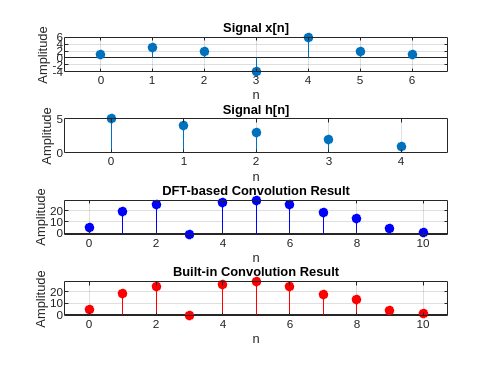

%activity 1.4:
function y = dft_based_conv(x, h)
    Nx = length(x);
    Nh = length(h);
    Ny = Nx + Nh - 1;
    xp = [x, zeros(1, Ny - Nx)];
    hp = [h, zeros(1, Ny - Nh)];
    Xp = fft(xp);
    Hp = fft(hp);
    Yp = Xp .* Hp;
    y = ifft(Yp);
    y = real(y);
end

x = [1,3,2,-4,6,2,1];
h = [5,4,3,2,1];
y_dft = dft_based_conv(x, h);
y_conv = conv(x, h);

%plotting results
figure;
subplot(4,1,1);
stem(0:length(x)-1, x, 'filled');
title('Signal x[n]');
xlabel('n');
ylabel('Amplitude');
grid on;

subplot(4,1,2);
stem(0:length(h)-1, h, 'filled');
title('Signal h[n]');
xlabel('n');
ylabel('Amplitude');
grid on;

subplot(4,1,3);
stem(0:length(y_dft)-1, y_dft, 'filled', 'b');
title('DFT-based Convolution Result');
xlabel('n');
ylabel('Amplitude');
grid on;

subplot(4,1,4);
stem(0:length(y_conv)-1, y_conv, 'r', 'filled');
title('Built-in Convolution Result');
xlabel('n');
ylabel('Amplitude');
grid on;


%comparing values
fprintf('\nComparison of Convolution Results:\n');


Comparison of Convolution Results:


fprintf('n\tDFT-based\tBuilt-in\tDifference\n');

n	DFT-based	Built-in	Difference


fprintf('----------------------------------------\n');

----------------------------------------


for i = 1:length(y_dft)
    fprintf('%d\t%f\t%f\t%e\n', i-1, y_dft(i), y_conv(i), abs(y_dft(i)-y_conv(i)));
end

0	5.000000	5.000000	5.329071e-15
1	19.000000	19.000000	3.552714e-15
2	25.000000	25.000000	0.000000e+00
3	-1.000000	-1.000000	2.664535e-15
4	27.000000	27.000000	0.000000e+00
5	29.000000	29.000000	0.000000e+00
6	25.000000	25.000000	0.000000e+00
7	18.000000	18.000000	0.000000e+00
8	13.000000	13.000000	1.776357e-15
9	4.000000	4.000000	2.664535e-15
10	1.000000	1.000000	2.664535e-15



fprintf('\nMaximum difference between methods: %e\n', max(abs(y_dft - y_conv)));


Maximum difference between methods: 5.329071e-15


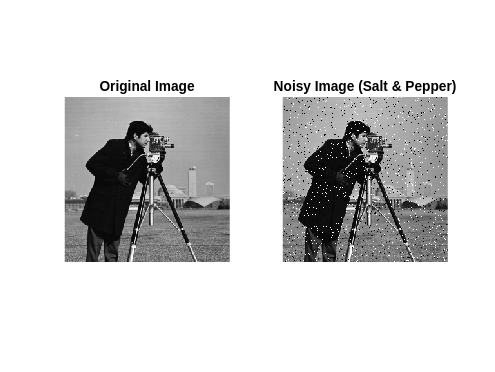

% Activity 1.5: Noise Removal Using 2D DFT and Low-Pass Filters

%loading the original image
xn = imread('cameraman.tif');

%adding salt-and-pepper noise to the image
xn_noisy = imnoise(xn, 'salt & pepper', 0.05);

%Plotting the original and noisy images
figure('Name', 'Original vs Noisy Image');
subplot(1,2,1); imshow(xn); title('Original Image');
subplot(1,2,2); imshow(xn_noisy); title('Noisy Image (Salt & Pepper)');

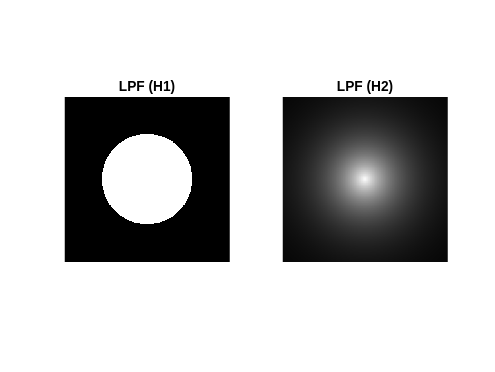


%(d) and (e): Converting to double, compute 2D FFT, and shift spectrum
X = fftshift(fft2(double(xn_noisy)));
[M, N] = size(X);

% Step (f)
[U, V] = meshgrid(1:N, 1:M);
D1 = 70; 
D2 = 50; 
p = 1; 
D = sqrt((U - M/2).^2 + (V - N/2).^2);

%ideal Low-Pass Filter (H1)
H1k = D <= D1;

%gaussian-like Low-Pass Filter (H2)
H2k = exp(-(D/D2).^p);

% Step (g):plotting the transfer functions of the filters
figure('Name', 'Filter Responses');
subplot(1,2,1); imshow(H1k); title('LPF (H1)');
subplot(1,2,2); imshow(H2k); title('LPF (H2)');

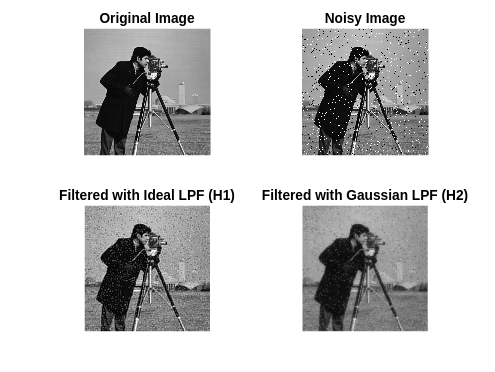


% Step(g):applying filters to the FFT of the noisy image
Y1 = X .* H1k; 
Y2 = X .* H2k; 

% Step (h) and (i):deleting FFT shift and compute inverse FFT
y1 = real(ifft2(ifftshift(Y1)));
y2 = real(ifft2(ifftshift(Y2)));

% Step (j): in uint8 format converting
y1_filtered = uint8(y1);
y2_filtered = uint8(y2);

figure('Name', 'Filtering Results');
subplot(2,2,1); imshow(xn); title('Original Image');
subplot(2,2,2); imshow(xn_noisy); title('Noisy Image');
subplot(2,2,3); imshow(y1_filtered); title('Filtered with Ideal LPF (H1)');
subplot(2,2,4); imshow(y2_filtered); title('Filtered with Gaussian LPF (H2)');

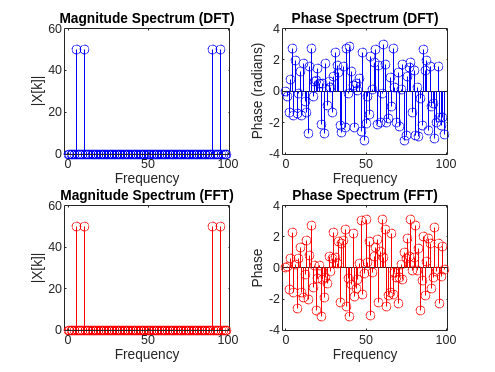

%Task 2
f1 = 5;  
f2 = 10; 
fs = 100;
n = 0:99;
x = sin(2 * pi * f1 * n / fs) + sin(2 * pi * f2 * n / fs);
N = length(x);
X_dft = zeros(1, N);
for k = 1:N
    for m = 1:N
        X_dft(k) = X_dft(k) + x(m) * exp(-1j * 2 * pi * (k-1) * (m-1) / N);
    end
end

X_fft = fft(x);

magnitude_of_dft = abs(X_dft);
phase_of_dft = angle(X_dft);
magnitude_of_fft = abs(X_fft);
phase_of_fft = angle(X_fft);

figure('Name', 'DFT and FFT Comparison');

subplot(2,2,1);
stem(0:N-1, magnitude_of_dft, 'b');
title('Magnitude Spectrum (DFT)');
xlabel('Frequency');
ylabel('|X[k]|');

subplot(2,2,2);
stem(0:N-1, phase_of_dft, 'b');
title('Phase Spectrum (DFT)');
xlabel('Frequency');
ylabel('Phase (radians)');

subplot(2,2,3);
stem(0:N-1, magnitude_of_fft, 'r');
title('Magnitude Spectrum (FFT)');
xlabel('Frequency');
ylabel('|X[k]|');

subplot(2,2,4);
stem(0:N-1, phase_of_fft, 'r');
title('Phase Spectrum (FFT)');
xlabel('Frequency');
ylabel('Phase');